clear 
clc 
close all

Wrocław 26.05.2021

Aleksander Kudyba   

245084

# Wyznaczanie rozkładu koncentracji nośników oraz pola elektrycznego w złączu m-s, przy wykorzystaniu jego charakterystyki pojemnościowo- napięciowej.

Dane z wykresu charakterystyki pojemnościowo- napięciwej złącza Schottky'ego na krzemie typu p pozwalają na oszacowanie koncentracji nośników i pola elektrycznego na złączu, w przypadku kiedy potencjał na złączu jest znany z rozwiązania równania Poisson'a, skąd obliczana jest szerkość obszaru zubożonego. Zakładając, że mamy do czynienia z obszarem zubożonym dla skokowego domieszkowania. możemy przybliżyć zależność pojemności złącza jako pojemność kondensatora płaskiego. Mamy więc pojemność wyrażoną  $C = \frac{A \varepsilon}{ \left( \frac{2 \varepsilon(V_{bi}-U)}{eN_d} \right) ^{\frac{1}{2}}} = \frac{A \varepsilon}{x_d} \rightarrow x_d = \frac{A \varepsilon}{C}$ , 

gdzie $x_d$ to szerokość obszru zubożonego, $A$- powierzchnia kontaktu, $V_{bi}$- potencjał wbudowany, $U$- zewnętrzne napięcie (w kierunku zaporowym).   

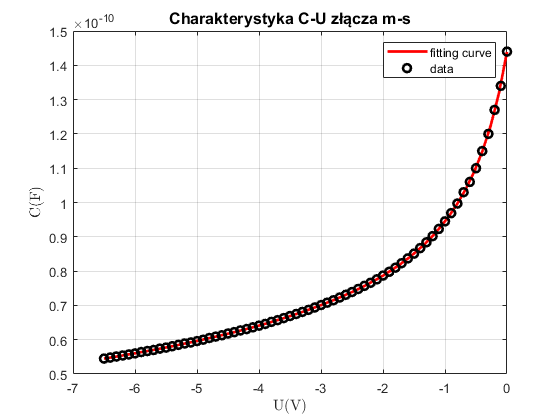

fileID = fopen('CV.dat');
C = textscan(fileID, '%s %s');
fclose(fileID);
a = C{1,1};
b = C{1,2};
a = a(3:end);
b = b(3:end);

for i=1:1:length(a)
    d{i} = str2double(a{i});
    e{i} = str2double(b{i});
    f(i) = d{i};  % U z pliku
    g(i) = e{i};  % C z pliku
end
p = polyfit(f,g,12);
U = linspace(-6.5,0,50);
C = polyval(p,U);

Amm = 2.01; %mm^2
A = Amm*1e-6; %m^2
eps_Si = 11.7; %F/m 
eps = eps_Si * 8.85417e-12; %F/m
q = 1.602e-19;
x = (A*eps)./C;

delta1 = mid_diff(U,C);
delta1_raw = mid_diff(f,g);
dU = diff(U);
dC = diff(C);
dU_raw = diff(f);
dC_raw = diff(g);
delta2 = dC./dU;
delta2_raw = dC_raw./dU_raw;

N1 = C.^3./(A^2*eps*q*delta1);
N2 = C(2:end).^3./(A^2*eps*q*delta2);
N3 = g.^3./(A^2*eps*q*delta1_raw);
N4 = g(2:end).^3./(A^2*eps*q*delta2_raw);
plot(U,C,'r-',f, g, 'ko', 'Linewidth', 2)
title('Charakterystyka C-U złącza m-s', 'Fontsize', 12)
xlabel("U(V)",'Interpreter','latex');
ylabel("C(F)",'Interpreter','latex');
legend("fitting curve", "data");

grid on

Żeby policzyć rozkład koncentracji ze wzoru $- \frac{C^3}{A^2 \varepsilon e} \left(\frac{\Delta C }{\Delta V_r} \right)^{-1}$ wyznaczamy numerycznie pochodną pojemności po napięciu. Do policzenia pochodnej użyto metody różnic skończonych, w dwóch wariantach: róznicy centralnej,  


$$\frac{df}{dx}= \frac{f \left(x_{i+1} \right)-f \left(x_{i-1} \right)}{x_{i+1}-x_{i-1}}$$


oraz w tył (która jest zaimplementowana w matlabie),

 $\frac{df}{dx}= \frac{f \left(x_{i} \right)-f \left(x_{i-1} \right)}{x_{}-x_{i-1}}$.

Najbardziej znaczący wpływ na dokładność metody ma gęstość siatki. W przypadku liczenia pochodnej bez wcześniejszej aproksymacji do ciągłej funkcji danych eksperymentalcych, na brak artefaktów w wykresach pochodnyvh będzie mieć wpływ błąd pomiaru i jak gęsto rozłożone są punkty pomiarowe, kiedy stosunkowo szybko zmieniają się ich warości. W poniższych wykresach warto tez odnotowć, że dokładność dla różnicy centralnej różni się nieznacznie od tej w tył, ze względu na dobór punktów z danych. Jeśli są one równomiernie rozłożone to wynik centralnej różnicy jest średnią różnicy w tył i w przód, stąd jest nadokładniejszym wariantem metod różnic skończonych.

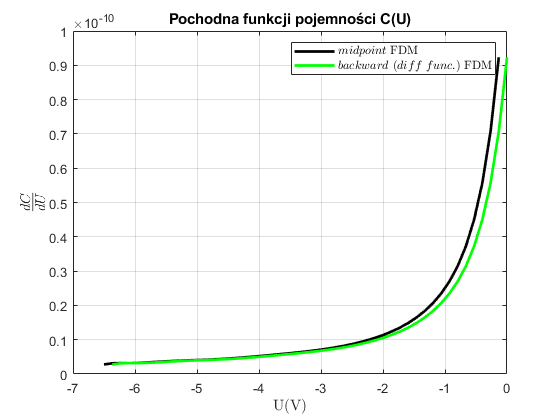

plot(U(1:end-1),delta1(1:end-1),'k-',U(2:end),delta2, 'g-', 'Linewidth', 2)
title('Pochodna funkcji pojemności C(U)','Fontsize', 11)
xlabel("U(V)",'Interpreter','latex');
ylabel("$\frac{dC}{dU}$",'Interpreter','latex','Fontsize', 15);
legend('$midpoint$ FDM','$backward$ $(diff$ $func.)$ FDM','Interpreter', 'latex')

grid on

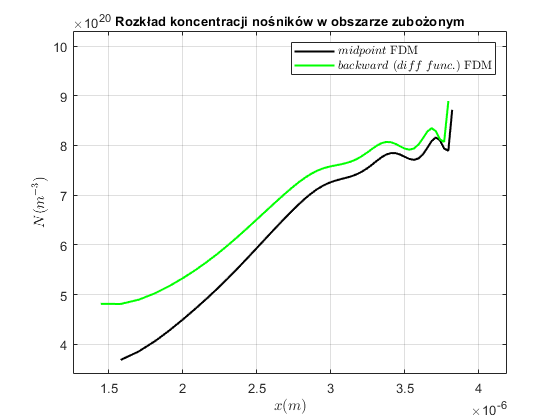

plot(x(1:end-1),N1(1:end-1),'k-',x(2:end),N2,'g-', 'Linewidth', 1.5)
title('Rozkład koncentracji nośników w obszarze zubożonym', 'Fontsize', 10)
legend('$midpoint$ FDM','$backward$ $(diff$ $func.)$ FDM','Interpreter', 'latex')
xlabel('$x(m)$','Interpreter', 'latex')
ylabel('$N(m^{-3})$','Interpreter', 'latex')
xlim([0.00000126 0.00000419])
ylim([340233223500822216704 1030320687057673650176])
grid on

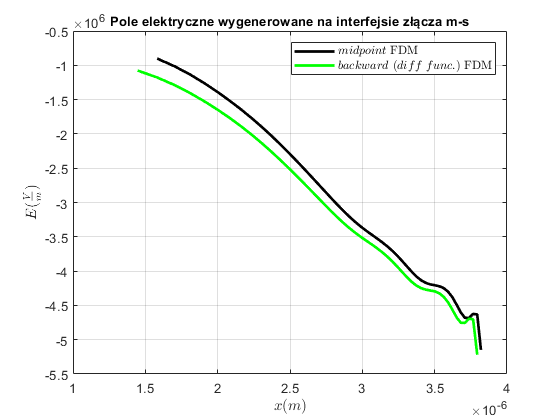

E1 = -(q.*N1./eps).*x;
E2 = -(q.*N2./eps).*x(2:end);
plot(x(1:end-1),E1(1:end-1),'k-',x(2:end),E2,'g-', 'Linewidth', 2)
title('Pole elektryczne wygenerowane na interfejsie złącza m-s', 'Fontsize', 10)
xlabel('$x(m)$','Interpreter', 'latex')
ylabel('$E(\frac{V}{m})$','Interpreter', 'latex')
legend('$midpoint$ FDM','$backward$ $(diff$ $func.)$ FDM','Interpreter', 'latex')
grid on

Korzystając w charakterystyki pojemnościowo- napięciowej dla rzeczywistego złącza m-s, od razu widać odstępstwa od przybliżenia obszru całkowicie zubożonego, w którym koncentracja nośników jest stała. W rzeczywistości uzyskanie takiego rozkładu jest bardzo trudne i mamy do czynienia z niejednorodnymi koncentracjami nośników. Mogą mieć na to wpływ poziomy pułapkowe lub pasywacja domieszek poprzez zewnętrzne czynniki. 

% 
% %pole liczysz z -(q*Na/eps)*xd a Na liczysz przy pomocy różniczki dC/dU

function deriv = mid_diff(x,y)
N = length(y);
deriv = zeros(1, N);
deriv(1) = (y(2) - y(1))/(x(2) - x(1));
for i=2:length(y)-1
    deriv(i) = (y(i+1) - y(i))/(x(i+1) - x(i));
end
deriv(N) = (y(N) - y(N-1))/(x(N) - x(N-1));
end
